# Merge both mooring deployments and create a nice figure

***Author: Lewis Drysdale, 2021***

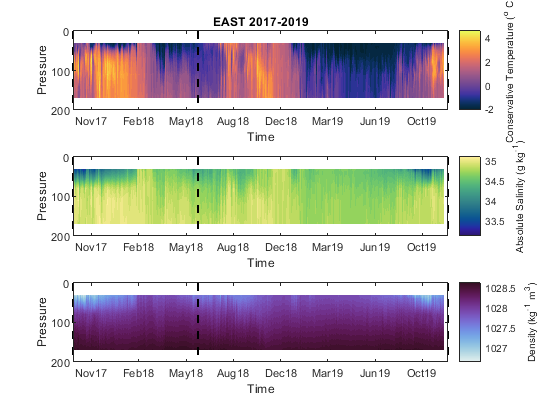


data_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\data\moor_processed';
plot_dir = 'M:\Mar_Phys\Moorings\PRIZE moorings\figures';

west_dr=[datenum('23-Sep-2017') datenum('14-Jun-2018')  datenum('22-Jun-2018') datenum('25-Nov-2019')];
east_dr=[datenum('23-Sep-2017') datenum('14-Jun-2018')  datenum('22-Jun-2018') datenum('25-Nov-2019')];


mid={'WEST','EAST'};
for jah=1:numel(mid)
    mooring_id=mid{jah};
    
    if strcmpi(mooring_id,'WEST')
        load(fullfile(data_dir, 'prize_west_17_gridded.mat'));
        load(fullfile(data_dir, 'prize_west_18_gridded.mat'));
        x=[prize_west_17_gridded.time_grid prize_west_18_gridded.time_grid];
        y=prize_west_18_gridded.pres_grid;
        zt=[prize_west_17_gridded.temp_filtered_interpolated prize_west_18_gridded.temp_filtered_interpolated];
        zs=[prize_west_17_gridded.sal_filtered_interpolated prize_west_18_gridded.sal_filtered_interpolated];   
        zrho = [prize_west_17_gridded.rho_filtered_interpolated prize_west_18_gridded.rho_filtered_interpolated];
            elseif strcmpi(mooring_id,'EAST')
        load(fullfile(data_dir, 'prize_east_17_gridded.mat'));
        load(fullfile(data_dir, 'prize_east_18_gridded.mat'));
        x=[prize_east_17_gridded.time_grid prize_east_18_gridded.time_grid];
        y=prize_east_18_gridded.pres_grid;
        zt=[prize_east_17_gridded.temp_filtered_interpolated prize_east_18_gridded.temp_filtered_interpolated];
        zrho = [prize_east_17_gridded.rho_filtered_interpolated prize_east_18_gridded.rho_filtered_interpolated];
        zs=[prize_east_17_gridded.sal_filtered_interpolated prize_east_18_gridded.sal_filtered_interpolated]; 
    else
        disp('No data to plot!')
    end


    figure(jah);
    
    ax(1)=subplot(3,1,1);
    [c,h]=contourf(x,y,zt,30,...
        'Linecolor','none');
    hold on
    axis ij
    cmocean('Thermal')
    C=colorbar;
    ylabel(C,'Conservative Temperature (^{o} C)')
    ylabel('Pressure')
    xlabel('Time')
    datetick('x',12,'Keeplimits','keepticks');
    plot([west_dr(1) west_dr(1)],[0 200],'--k','LineWidth',1.5);
    plot([west_dr(2) west_dr(2)],[0 200],'--k','LineWidth',1.5);
    plot([west_dr(4) west_dr(4)],[0 200],'--k','LineWidth',1.5);
    
    title([mooring_id ' 2017-2019']) ;

    ax(2)=subplot(3,1,2);
    [c,h]=contourf(x,y,zs,30,...
        'Linecolor','none');
    axis ij
    cmocean('Haline')
    C=colorbar;
    ylabel(C,'Absolute Salinity (g kg^{-1})')
    ylabel('Pressure')
    xlabel('Time')
    datetick('x',12,'Keeplimits','keepticks');
   
    hold on
    plot([west_dr(1) west_dr(1)],[0 200],'--k','LineWidth',1.5);
    plot([west_dr(2) west_dr(2)],[0 200],'--k','LineWidth',1.5);
    plot([west_dr(4) west_dr(4)],[0 200],'--k','LineWidth',1.5);
    
    ax(3)=subplot(3,1,3);
    [c,h]=contourf(x,y,zrho,30,...
        'Linecolor','none');
    axis ij
    cmocean('Dense')
    C=colorbar;
    ylabel(C,'Density (kg^{-1} m^{3})')
    ylabel('Pressure')
    xlabel('Time')
    datetick('x',12,'Keeplimits','keepticks'); 
    hold on
    plot([west_dr(1) west_dr(1)],[0 200],'--k','LineWidth',1.5);
    plot([west_dr(2) west_dr(2)],[0 200],'--k','LineWidth',1.5);
    plot([west_dr(4) west_dr(4)],[0 200],'--k','LineWidth',1.5);
        
    savename=[plot_dir filesep mooring_id '_MERGED'];
    
    print(gcf, '-dpng',savename);
end